Data loading (given script).

loaddata

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat
    flipped responses for block 1!
../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../


dout = '../Out/' % folder for produced data

dout = '../Out/'

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal and the choice probability.

nrep = 10;

clear prev_fit beta_fit % to prevent any dimension error when using MATLAB LiveScript environment 
[prev_fit, beta_fit] = initialfit(nrep, nsubj, dat, subjlist);

mean_prev_fit = mean(prev_fit(:))

mean_prev_fit = 0.2087

mean_beta_fit = mean(beta_fit(:))

mean_beta_fit = 1.2439

Using a function "sim_model_softmax", datasets are simulated using different values as fixed parameters, in order to study the ability of the fitting procedure to recover a certain different within a parameter while the other is kept constant (see 'ndiff'; nsim simulated datasets).

nsim              = 30;                % number of simulations
nttest            = 100;               % number of ttests
ndiff             = [0      0   ; ...  % couples of differences to be tested
                     0.01   0   ; ...
                     0.02   0   ; ...
                     0.03   0   ; ...
                     0.04   0   ; ...
                     0.05   0   ; ...
                     0.1    0   ; ...
                     0      0.1 ; ...
                     0      0.2 ; ...
                     0      0.3 ; ...
                     0      0.4 ; ...
                     0      0.5 ; ...
                     0      1   ]     

ndiff =          0         0
    0.0100         0
    0.0200         0
    0.0300         0
    0.0400         0
    0.0500         0
    0.1000         0
         0    0.1000
         0    0.2000
         0    0.3000


nsubjsubset       = [24]              % subset(s) of participants (w/out consideration for medical condition, 96 = all)

nsubjsubset = 24


% preallocation
prev_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1); % significant ttest counter across the differences tested
beta_diffsigni_acrossdiff = zeros(1, 2, length(nsubjsubset), 1);

revindexdiff = 0 % initilisation of difference counter

revindexdiff = 0

for idiff = ndiff'
    revindexdiff = revindexdiff + 1; % to facilitate iteration of the differences outside the loop
    
    idiff % to display the difference being computed in MATLAB LiveScript environment 
    prev_fix = [mean_prev_fit-(idiff(1)/2) mean_prev_fit+(idiff(1)/2)]
    beta_fix = [mean_beta_fit-(idiff(2)/2) mean_beta_fit+(idiff(2)/2)]
    
    % preallocation
    prev_ttest = zeros(nttest, 5, length(nsubjsubset)); % ttest results saved
    beta_ttest = zeros(nttest, 5, length(nsubjsubset));
    
    prev_diffsigni = zeros(1, 2, length(nsubjsubset)); % significant ttest counter
    beta_diffsigni = zeros(1, 2, length(nsubjsubset));
    
    for isubjsubset = nsubjsubset
            % preallocation
            prev_recov = zeros(isubjsubset, 2, nsim);
            beta_recov = zeros(isubjsubset, 2, nsim);
            
            isubjsubset % to display the current subset running in MATLAB LiveScript environment 
            seq_isubjsubsest = randperm(nsubj, isubjsubset) % to avoid selecting deterministically the same subjects across subsets
        for ittest = 1:nttest
            for isubj = seq_isubjsubsest
            % given script -->
                for itask = 1:2
                    
                    % filter trials of interest
                    ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
                    
                    % simulate model
                    cfg_sim        = [];
                    cfg_sim.nsim   = nsim;
                    cfg_sim.seqllr = dat.evid(ifilt);
                    cfg_sim.seqind = dat.sind(ifilt);
                    cfg_sim.prev   = prev_fix(itask);
                    cfg_sim.beta   = beta_fix(itask);
                    cfg_sim.brep   = 0; % force no repetition bias
                    cfg_sim.epsi   = 0; % force no lapses
                    
                    out_sim        = sim_model_softmax(cfg_sim);
                

        Then each datasets is fit using the function "fit_model_softmax".

                    % fit simulated decisions
                    for isim = 1:nsim
                        cfg_fit        = [];
                        cfg_fit.seqllr = out_sim.cfg.seqllr;
                        cfg_fit.seqind = out_sim.cfg.seqind;
                        cfg_fit.raft   = out_sim.raft(:, isim);
                        cfg_fit.rbef   = out_sim.rbef(:, isim);
                        cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                        cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                            
                        out_recov = fit_model_softmax(cfg_fit);
            % <-- given script                        

        Estimated values of prev and beta from each simulation are stored and their average value is computed.

                        % store model parameters
                        revindexsubj = find(seq_isubjsubsest==isubj); % isubj goes over the index limit due to the 
                                                                      % use of subsets --> reverse indexing
                        prev_recov(revindexsubj, itask, isim) = out_recov.prev;
                        beta_recov(revindexsubj, itask, isim) = out_recov.beta;
                    end    
                end
            end

        Paired-sample t-test + data saving for each given difference (ndiff).

            revindexsubset = find(nsubjsubset == isubjsubset);    
            
            [h,p,ci,stats] = ttest(prev_recov(1, 1, :),prev_recov(1, 2, :));
            prev_ttest(ittest, 1, revindexsubset) = h;
            prev_ttest(ittest, 2, revindexsubset) = p;
            prev_ttest(ittest, 3, revindexsubset) = ci(:, :, 1);
            prev_ttest(ittest, 4, revindexsubset) = ci(:, :, 2);
            prev_ttest(ittest, 5, revindexsubset) = stats.sd;
            
            [h,p,ci,stats] = ttest(beta_recov(1, 1, :),beta_recov(1, 2, :));
            beta_ttest(ittest, 1, revindexsubset) = h;
            beta_ttest(ittest, 2, revindexsubset) = p;
            beta_ttest(ittest, 3, revindexsubset) = ci(:, :, 1);
            beta_ttest(ittest, 4, revindexsubset) = ci(:, :, 2);
            beta_ttest(ittest, 5, revindexsubset) = stats.sd;
            
        end
        
        prev_diffsigni(:, :, revindexsubset) = [length(find(prev_ttest(:, 1, revindexsubset) == 1)) nttest]; %ttest counter
        beta_diffsigni(:, :, revindexsubset) = [length(find(beta_ttest(:, 1, revindexsubset) == 1)) nttest];
        
        
    end
    
    prev_diffsigni_acrossdiff(:, :, :, revindexdiff) = prev_diffsigni % to save data across differences tested
    beta_diffsigni_acrossdiff(:, :, :, revindexdiff) = beta_diffsigni % displayed in MATLAB LiveScript environment
    
    str_nsubjsubset = ''; % to nicely convert nsubjsubset into a string, e.g., "12-24-48-96"
    for isubjsubset = nsubjsubset
        str_nsubjsubset = [str_nsubjsubset, num2str(isubjsubset), '-'];
    end
    str_nsubjsubset = str_nsubjsubset(1:end-1) % to delete the last (useless) '-'
    
    formatSpec_file = '%s%s_(%g-%g)diff_%ssubj_%dx%dsim.mat';
    
    name_file = sprintf(formatSpec_file, dout,'prev_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_file, 'dout', 'ndiff', 'idiff', 'nsubjsubset', 'nsim', 'nttest', 'prev_ttest', 'prev_diffsigni')
    
    name_file = sprintf(formatSpec_file, dout,'beta_ttest',idiff(1),idiff(2),str_nsubjsubset,nttest,nsim);
    save(name_file, 'dout', 'ndiff', 'idiff', 'nsubjsubset', 'nsim', 'nttest', 'beta_ttest', 'beta_diffsigni')
      
end

idiff =      0
     0


prev_fix =     0.2087    0.2087


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     85    40    67    35    24    64    77     7    87    60    11    92    47    25    73    94    71    91     6    72    42    13    57    51


prev_diffsigni_acrossdiff =      6   100


beta_diffsigni_acrossdiff =      5   100


str_nsubjsubset = '24'

idiff =     0.0100
         0


prev_fix =     0.2037    0.2137


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     65    55    63    15    13    96     2    95    78    39    67     9    64    28    50    21    68    23    58    11    40    44    14    87


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


str_nsubjsubset = '24'

idiff =     0.0200
         0


prev_fix =     0.1987    0.2187


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     57    17    44    14    30    80    38     6    81    16    71    68    18    66     7    36    41    83    20    10    92    31     1    63


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


str_nsubjsubset = '24'

idiff =     0.0300
         0


prev_fix =     0.1937    0.2237


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     17    49    88    37    48    34    93    89    23    82     9    43    60    13    65    38    36    83    61    72    30    16    18    95


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


str_nsubjsubset = '24'

idiff =     0.0400
         0


prev_fix =     0.1887    0.2287


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     53    56    57    69    23    92    36     4    29    24    28    94    89    58    68    82    93    90    26    88    35    21     1    30


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


str_nsubjsubset = '24'

idiff =     0.0500
         0


prev_fix =     0.1837    0.2337


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     70    85    79    35    45     5     6    86    58    33    89    71    60    42    29    44    37    20    65    19    14    69    95    26


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


str_nsubjsubset = '24'

idiff =     0.1000
         0


prev_fix =     0.1587    0.2587


beta_fix =     1.2439    1.2439


isubjsubset = 24

seq_isubjsubsest =     33    86    77    84    13    43    63    59    93    44    73    35    25    87    90    67    74    52    88    29    68    23    64    78


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


str_nsubjsubset = '24'

idiff =          0
    0.1000


prev_fix =     0.2087    0.2087


beta_fix =     1.1939    1.2939


isubjsubset = 24

seq_isubjsubsest =     74    12    15    89    80     9    71    62     4    46    54    90    21    94    41    39    67    49    20    45    48     3    92    17


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


str_nsubjsubset = '24'

idiff =          0
    0.2000


prev_fix =     0.2087    0.2087


beta_fix =     1.1439    1.3439


isubjsubset = 24

seq_isubjsubsest =     68    33    17    31    65    79    80    18    13    55    20     2    71     3    90    29     4    59    69    48    15    57    63    19


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     6   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    85   100


str_nsubjsubset = '24'

idiff =          0
    0.3000


prev_fix =     0.2087    0.2087


beta_fix =     1.0939    1.3939


isubjsubset = 24

seq_isubjsubsest =     96    24    88    81     3    57    67    38    66    34    84    76    52    86     1    37    64    54    53    63    42    32    89    27


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     2   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    85   100


beta_diffsigni_acrossdiff(:,:,1,10) =

    99   100


str_nsubjsubset = '24'

idiff =          0
    0.4000


prev_fix =     0.2087    0.2087


beta_fix =     1.0439    1.4439


isubjsubset = 24

seq_isubjsubsest =     41     4    25    61    24    19    95    78    56    52    38    74    33    60     7    53    40    55    91    11    66    34     1     6


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     2   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     4   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    85   100


beta_diffsigni_acrossdiff(:,:,1,10) =

    99   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


str_nsubjsubset = '24'

idiff =          0
    0.5000


prev_fix =     0.2087    0.2087


beta_fix =     0.9939    1.4939


isubjsubset = 24

seq_isubjsubsest =     64    23    90    93    61    41    36    27    65    12    43    46    89    95    75    78    21    52    63    51    37    32    24    59


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     2   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     4   100


prev_diffsigni_acrossdiff(:,:,1,12) =

     3   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    85   100


beta_diffsigni_acrossdiff(:,:,1,10) =

    99   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,12) =

   100   100


str_nsubjsubset = '24'

idiff =      0
     1


prev_fix =     0.2087    0.2087


beta_fix =     0.7439    1.7439


isubjsubset = 24

seq_isubjsubsest =      9    84    56    47    83    95    39    73    34    50    71    67    25    27    57    43    22    19     7    87    54    48    61    59


prev_diffsigni_acrossdiff = prev_diffsigni_acrossdiff(:,:,1,1) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,2) =

     9   100


prev_diffsigni_acrossdiff(:,:,1,3) =

    22   100


prev_diffsigni_acrossdiff(:,:,1,4) =

    55   100


prev_diffsigni_acrossdiff(:,:,1,5) =

    81   100


prev_diffsigni_acrossdiff(:,:,1,6) =

    95   100


prev_diffsigni_acrossdiff(:,:,1,7) =

   100   100


prev_diffsigni_acrossdiff(:,:,1,8) =

     7   100


prev_diffsigni_acrossdiff(:,:,1,9) =

     6   100


prev_diffsigni_acrossdiff(:,:,1,10) =

     2   100


prev_diffsigni_acrossdiff(:,:,1,11) =

     4   100


prev_diffsigni_acrossdiff(:,:,1,12) =

     3   100


prev_diffsigni_acrossdiff(:,:,1,13) =

     7   100


beta_diffsigni_acrossdiff = beta_diffsigni_acrossdiff(:,:,1,1) =

     5   100


beta_diffsigni_acrossdiff(:,:,1,2) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,3) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,4) =

     7   100


beta_diffsigni_acrossdiff(:,:,1,5) =

     4   100


beta_diffsigni_acrossdiff(:,:,1,6) =

     2   100


beta_diffsigni_acrossdiff(:,:,1,7) =

     3   100


beta_diffsigni_acrossdiff(:,:,1,8) =

    31   100


beta_diffsigni_acrossdiff(:,:,1,9) =

    85   100


beta_diffsigni_acrossdiff(:,:,1,10) =

    99   100


beta_diffsigni_acrossdiff(:,:,1,11) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,12) =

   100   100


beta_diffsigni_acrossdiff(:,:,1,13) =

   100   100


str_nsubjsubset = '24'

Plot of significant t-tests as a function of the difference in value for each parameter (only works while the value of the other is kept constant).

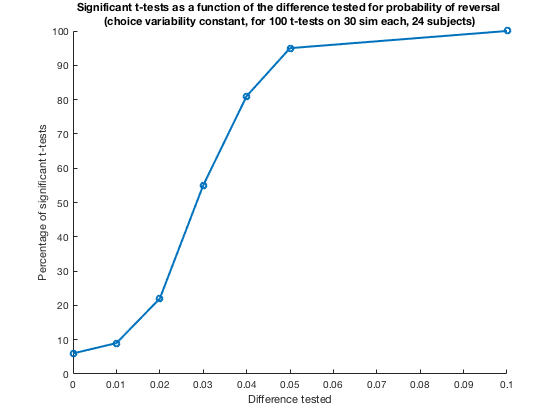

prevonly_diff_index = [1 2 3 4 5 6 7]    ; % to enter manually according to respective index in 'ndiff'
finalplots_mindiff(dout, nsubjsubset, nsim, nttest, ndiff, 1, prevonly_diff_index,     ...
                         prev_diffsigni_acrossdiff, 'probability of reversal', 'prev', ...
                         'choice variability')

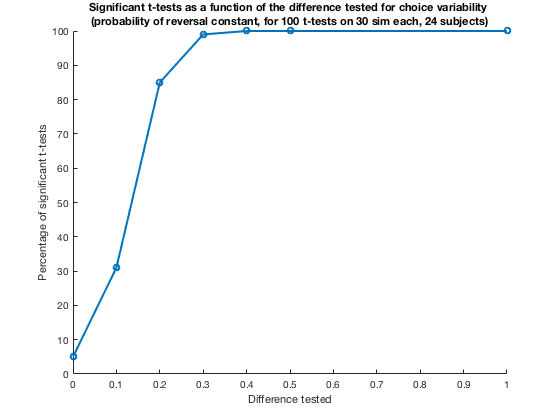

                         
betaonly_diff_index = [1 8 9 10 11 12 13]; % to enter manually according to respective index in 'ndiff'
finalplots_mindiff(dout, nsubjsubset, nsim, nttest, ndiff, 2, betaonly_diff_index,     ...
                         beta_diffsigni_acrossdiff, 'choice variability', 'beta',      ...
                         'probability of reversal')                  

Final workscape saving.

formatSpec_file = '%s%s_diffsigni_across%ddiff_%dsubj_%dx%dsim%s'

formatSpec_file = '%s%s_diffsigni_across%ddiff_%dsubj_%dx%dsim%s'


name_file = sprintf(formatSpec_file, dout, 'all', length(prevonly_diff_index), str_nsubjsubset, nttest, nsim, '.mat');
save(name_file) % to save the whole workspace

% To save only the variables needed for plotting:
% name_file = sprintf(formatSpec_file, dout, 'prev', length(prevonly_diff_index), str_nsubjsubset, nttest, nsim, '.mat');
% save(name_file, 'dout', 'nsubjsubset', 'nttest', 'ndiff', 'nsim','nttest','prev_diffsigni_acrossdiff', 'prevonly_diff_index')
% 
% name_file = sprintf(formatSpec_file, dout, 'beta', length(prevonly_diff_index), str_nsubjsubset, nttest, nsim, '.mat');
% save(name_file, 'dout', 'nsubjsubset', 'nttest', 'ndiff', 'nsim','nttest','beta_diffsigni_acrossdiff', 'betaonly_diff_index')
